## This is a simulation for a row of toppling dominoes with increasing sizes

clear

Dimensions of the initial domino brick in meters.

height = 5.08/100;
width = 2.54/100;
thickness = 0.9525/100;

Starting distance between the first and second brick

distance = 1/100;

Density of the material for calculating the mass

density = 940;
mass = (height*width*thickness*density);

Conditions for running the simulation

bricks = 12;
simulation_Time = 5;
step_size = 0.001;
samples = simulation_Time/step_size;

Calling the function eulercalc which returns the euler approximation of the first domino. The return values are arrays for the angle, angular acceleration, angular velocity and force created from gravitational pull on the domino.

[theta, acc, omega,mg] = eulercalc(simulation_Time,step_size,mass,thickness,height);
tot_ang = zeros(1,samples,bricks);

Saving the angle traveled of the first domino into an array for simulation.

tot_ang(:,:,1) = theta;

The angle for which the current domino can tilt before colliding with the next domino is saved into *b*. *distance *and *height * are increased with the same factor and will always have the same relation.

b = acos(distance/height);
collision_angle = (pi/2)-b;

for c = 2:1:bricks

The sample point of when the current domino is going to collide with the next is determined.

    k = find(theta < collision_angle, 1, 'last' );


*x *is the side of the next domino at the point of impact.

    x = sin(b)*height;

Increasing the size of the next domino and calculating the new mass, inertia and the perpendicular force. And the euler approximation is then preformed with the function *eulercalc_rest* and the traveled angle is saved for simulation.

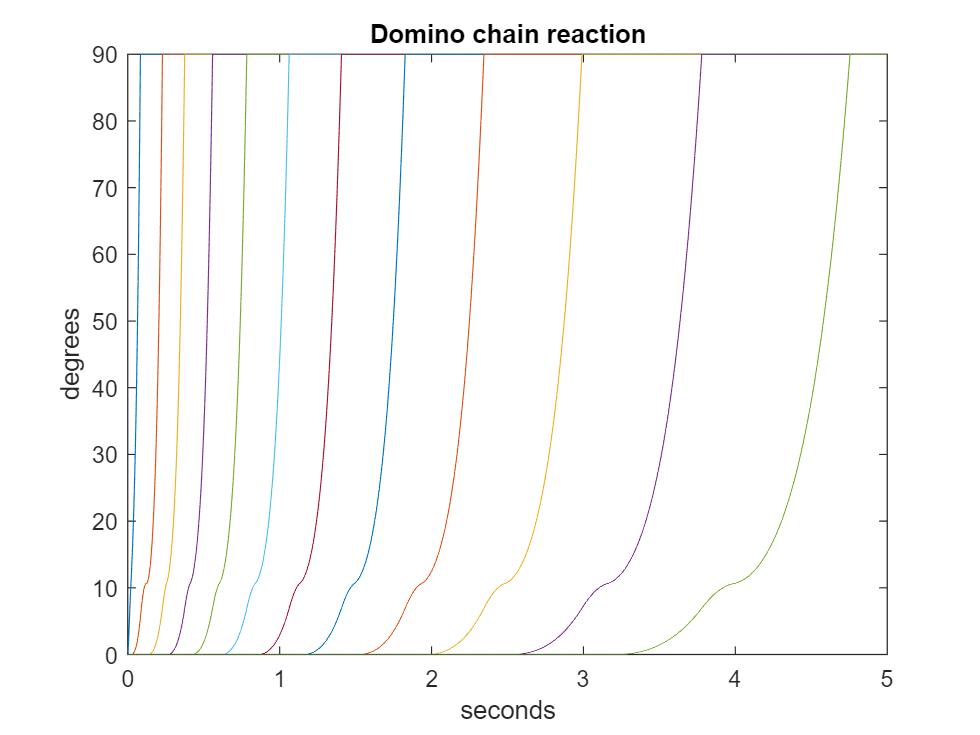

    height = height*1.5;
    width = width*1.5;
    thickness = thickness*1.5;
    mass = (height*width*thickness*density);
    J = mass*(height^2+thickness^2)/12;

    r = sqrt(thickness^2+x^2);
    Fr = acc(k)*J/height;
    Fx = Fr/cos(collision_angle);

    [theta, acc, omega, new_mg] = eulercalc_rest(simulation_Time,step_size,mass,thickness,height,Fx,mg,r,k);

    tot_ang(:,:,c) = theta;
    mg = new_mg;
    distance = distance*1.5;

end

t = 0:step_size:simulation_Time-step_size;

for m= 1:1:bricks
    plot(t,rad2deg(tot_ang(:,:,m)))
    hold on;
end


title('Domino chain reaction')
xlabel('seconds')
ylabel('degrees')